## Instance Sets Experiment 6

In this notebook we are going to create random models of SHH, CHH, and HH^4 and see its performance when solving a set of 240 instances: 

Instances_Comb

The SHH models will have access to FM_HH1, FM_HH2, and FM_HH3. 

The CHH models will have access to FM_SHH1, FM_SHH2, FM_SHH3, FM_SHH4, and FM_SHH5.

The HH^4 models will have access to the best solvers so far. 

The parameters of the HH models will vary from 1-5 rules, and from 1-5 features.

 **CLEANING AND FOLDERS**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**LOADING FILES**

%Loading sets of instances
load('instances_adv1.mat')
load('instances_adv2.mat')
load('instances_adv1_adv2_comb.mat')

%Loading heuristics
load('LPT.mat')
load('SPT.mat')
load('MPA.mat')
load('LPA.mat')
%load('LPT_multi.mat')
%load('SPT_multi.mat')
load('MPA_multi.mat')
load('LPA_multi.mat')

%Loading HHs 
load('FM_HH1_multi.mat')
load('FM_HH2_multi.mat')
load('FM_HH3_multi.mat')

%Loading SHH1-SHH5
load("FM_SHH1.mat")
load("FM_SHH2.mat")
load("FM_SHH3.mat")
load("FM_SHH4.mat")
load("FM_SHH5.mat")

%Loading randSHH and randCHH
%load('IS_Exp6_randSHH 4.mat')
%load('IS_Exp6_randCHH 4.mat')
load('solvedInstances_IS_Exp6_randCHH_comb_makespans.mat')
load('solvedInstances_IS_Exp6_randSHH_comb_makespans.mat')

**SHH RANDOM MODELS**

%Hyper-Parameters 
nbRanModels=100;
nbFeatures=31; 
nbRules=5; 
%Combination of features
Features={[1] [2] [3] [4] [5] [1 2] [1 3] [1 4] [1 5] [2 3] [2 4] [2 5] [3 4] [3 5] [4 5] [1 2 3] [1 2 4] [1 2 5] [1 3 4] [1 3 5] [1 4 5] [2 3 4] [2 3 5] [2 4 5] [3 4 5] [1 2 3 4] [1 2 3 5] [1 2 4 5] [1 3 4 5] [2 3 4 5] [1 2 3 4 5]};
%Creating empty 3-D Matrix
IS_Exp6_randSHH=cell(nbRanModels,nbFeatures,nbRules);

%Disabling displaying of warnings
warning('off')

%Creating 3-D Matrix
for z=1:nbRules
    for y=1:nbFeatures
        for x=1:nbRanModels
            %creating de models with 2 layers, z rules, 3 solvers and y features
            props = struct('nbLayers',2,'selectedSolvers',1:3,...
                             'nbRules',z,'innerHHs',[FM_HH1_multi FM_HH2_multi FM_HH3_multi],'selectedFeatures', Features(y));
            IS_Exp6_randSHH{x,y,z}=ruleBasedSelectionHHMulti(props);
        end
    end
end

save('IS_Exp6_randSHH','IS_Exp6_randSHH')

**CHH RANDOM MODELS**

%Hyper-Parameters 
nbRanModels=100;
nbFeatures=31; 
nbRules=5; 
%Combination of features
Features={[1] [2] [3] [4] [5] [1 2] [1 3] [1 4] [1 5] [2 3] [2 4] [2 5] [3 4] [3 5] [4 5] [1 2 3] [1 2 4] [1 2 5] [1 3 4] [1 3 5] [1 4 5] [2 3 4] [2 3 5] [2 4 5] [3 4 5] [1 2 3 4] [1 2 3 5] [1 2 4 5] [1 3 4 5] [2 3 4 5] [1 2 3 4 5]};
%Creating empty 3D-Matrix
IS_Exp6_randCHH=cell(nbRanModels,nbFeatures,nbRules);

%Disabling displaying of warnings
warning('off')

%Creating 3D Matrix of CHHs
for z=1:nbRules
    for y=1:nbFeatures
        for x=1:nbRanModels
            %creating de models with 3 layers, z rules, 5 solvers and y features
            props = struct('nbLayers',3,'selectedSolvers',1:5,...
                             'nbRules',z,'innerHHs',[FM_SHH1 FM_SHH2 FM_SHH3 FM_SHH4 FM_SHH5],'selectedFeatures', Features{y});
            IS_Exp6_randCHH{x,y,z}=ruleBasedSelectionHHMulti(props);
        end
    end
end

save('IS_Exp6_randCHH','IS_Exp6_randCHH')

**TESTING SHH AND CHH MODELS **

**1) Solving instances**

%INITIALIZING VARIABLES
nbModels=size(IS_Exp6_randCHH,1);
nbFeatures=size(IS_Exp6_randCHH,2);
nbRules=size(IS_Exp6_randCHH,3);

%Creating empty matrices for storing makespans
%solvedInstances_IS_Exp6_randSHH_comb=cell(nbModels,nbFeatures,nbRules);
%solvedInstances_IS_Exp6_randCHH_comb=cell(nbModels,nbFeatures,nbRules);
%solvedInstances_IS_Exp6_randCHH_comb_makespans=nan(length(instances_comb),nbModels,nbFeatures,nbRules);
%solvedInstances_IS_Exp6_randSHH_comb_makespans=nan(length(instances_comb),nbModels,nbFeatures,nbRules);
load("solvedInstances_IS_Exp6_randCHH_comb_makespans.mat")
load("solvedInstances_IS_Exp6_randSHH_comb_makespans.mat")
for y=9:nbFeatures
    disp("y=")
    disp(y)
    for z=1:nbRules
        disp("z=")
        disp(z)
            for x=1:nbModels
                %disp("x=")
                %disp(x)
                solvedInstances_IS_Exp6_randCHH_comb=IS_Exp6_randCHH{x,y,z}.solveInstanceSet(instances_comb);
                solvedInstances_IS_Exp6_randSHH_comb=IS_Exp6_randSHH{x,y,z}.solveInstanceSet(instances_comb);

                for i=1:length(instances_comb)
                    solvedInstances_IS_Exp6_randCHH_comb_makespans(i,x,y,z)=solvedInstances_IS_Exp6_randCHH_comb{i}.solution.makespan;
                    solvedInstances_IS_Exp6_randSHH_comb_makespans(i,x,y,z)=solvedInstances_IS_Exp6_randSHH_comb{i}.solution.makespan;
                end
            end
            save('solvedInstances_IS_Exp6_randSHH_comb_makespans','solvedInstances_IS_Exp6_randSHH_comb_makespans')
            save('solvedInstances_IS_Exp6_randCHH_comb_makespans','solvedInstances_IS_Exp6_randCHH_comb_makespans')
    end
end

y=


     9



z=


     1



save('solvedInstances_IS_Exp6_randSHH_comb_makespans','solvedInstances_IS_Exp6_randSHH_comb_makespans')
save('solvedInstances_IS_Exp6_randCHH_comb_makespans','solvedInstances_IS_Exp6_randCHH_comb_makespans')


**VISUALIZATION SO FAR **

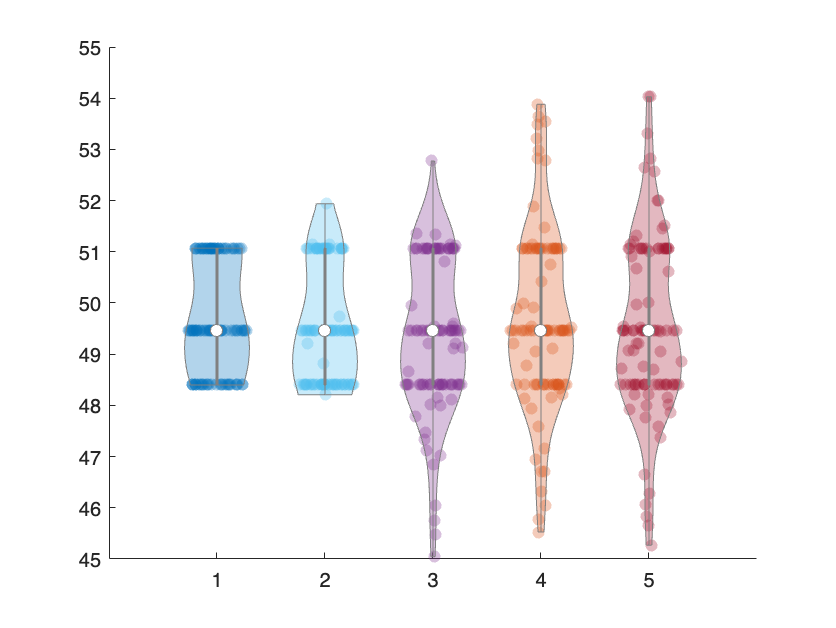

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Plotting the mean of the 100 iterations of the random SHH over
%intances_comb from rule 1-5, feature 1 
results_IS_Exp6_randSHH_means=squeeze(mean(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,1,:)));
figure
violinplot(results_IS_Exp6_randSHH_means)

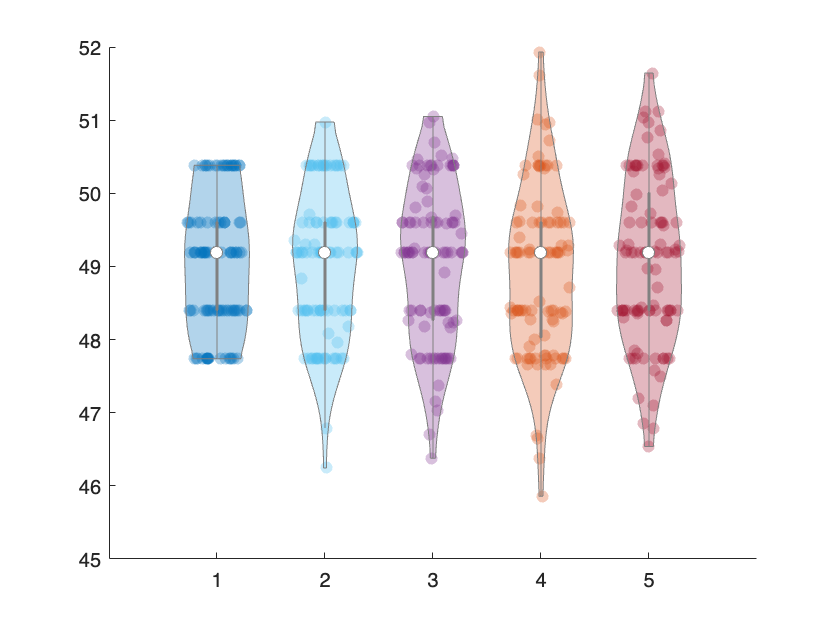

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Plotting the mean of the 100 iterations of the random CHH over
%intances_comb from rule 1-5, feature 1 
results_IS_Exp6_randCHH_means=squeeze(mean(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,1,:)));
figure
violinplot(results_IS_Exp6_randCHH_means)

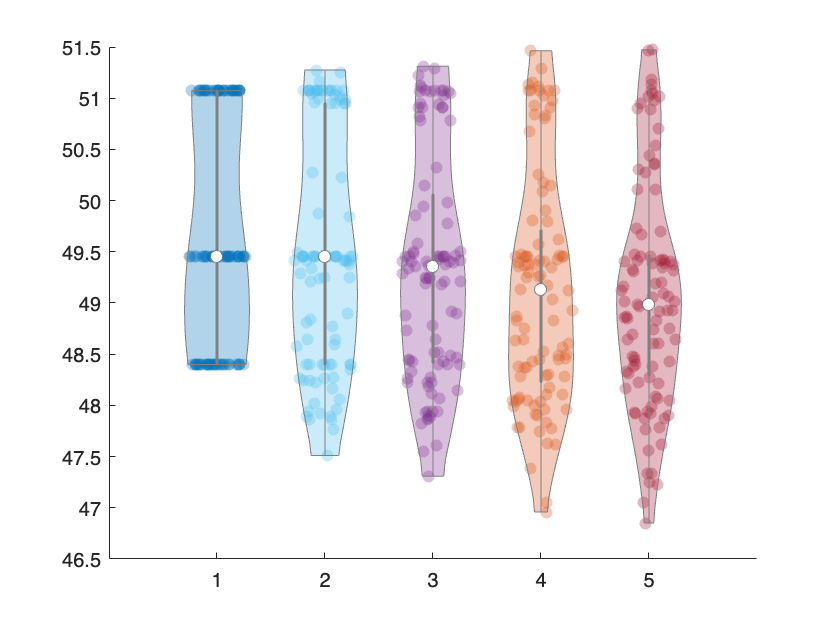

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Plotting the mean of the 100 iterations of the random SHH over intances_comb from rule 1-5,feature 2 
results_IS_Exp6_randSHH_means=squeeze(mean(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,2,:)));
figure
violinplot(results_IS_Exp6_randSHH_means)

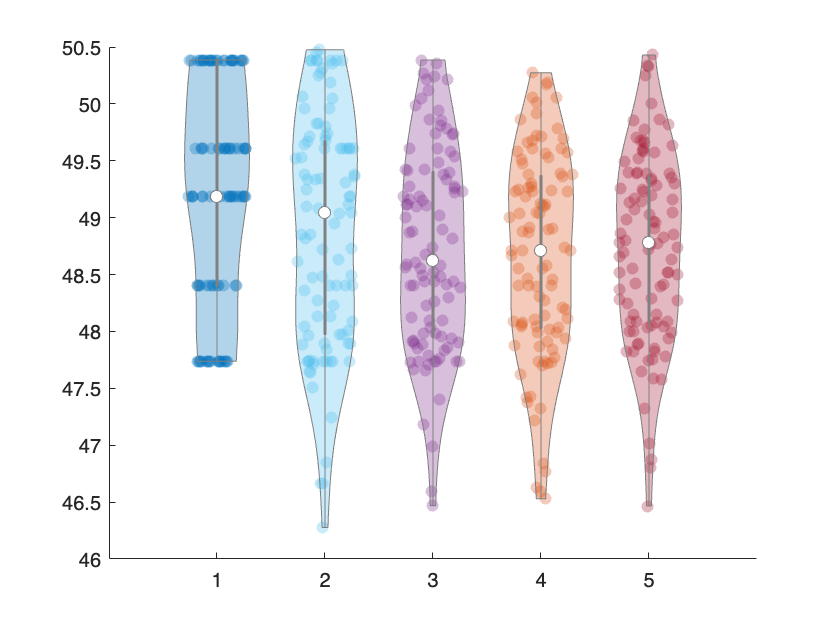

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Plotting the mean of the 100 iterations of the random SHH over intances_comb from rule 1-5, feature 2 
results_IS_Exp6_randCHH_means=squeeze(mean(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,2,:)));
figure
violinplot(results_IS_Exp6_randCHH_means)

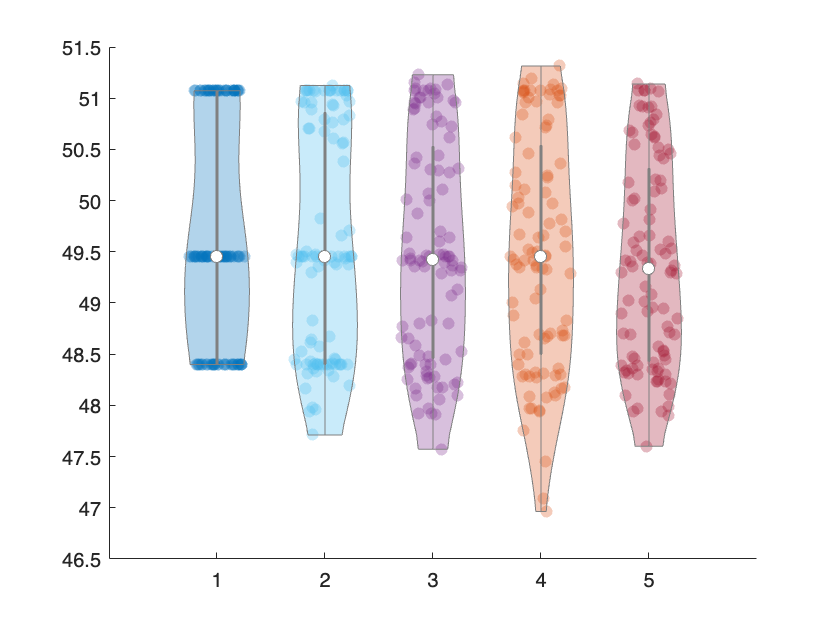

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean


%Plotting the mean of the 100 iterations of the random SHH over intances_comb from rule 1-5, feature 3 
results_IS_Exp6_randSHH_means=squeeze(mean(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,3,:)));
figure
violinplot(results_IS_Exp6_randSHH_means)

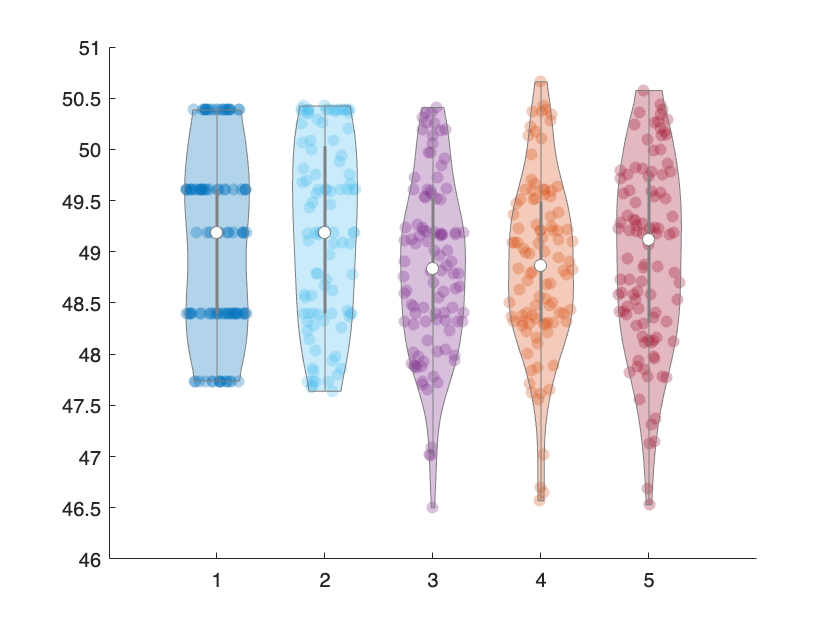

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean



%Plotting the mean of the 100 iterations of the random CHH over intances_comb from rule 1-5, feature 3 
results_IS_Exp6_randCHH_means=squeeze(mean(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,3,:)));
figure
violinplot(results_IS_Exp6_randCHH_means)

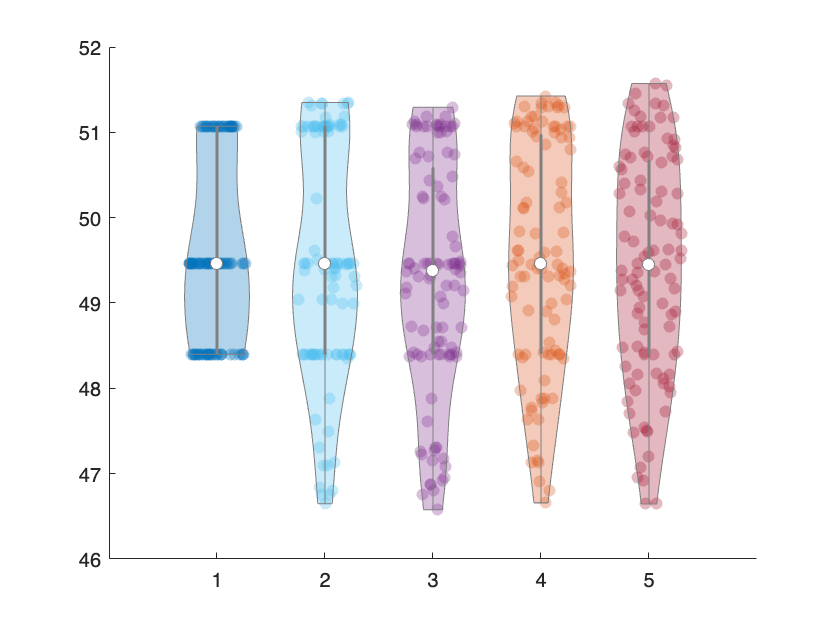

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean



%Plotting the mean of the 100 iterations of the random SHH over intances_comb from rule 1-5, feature 4 
results_IS_Exp6_randSHH_means=squeeze(mean(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,4,:)));
figure
violinplot(results_IS_Exp6_randSHH_means)

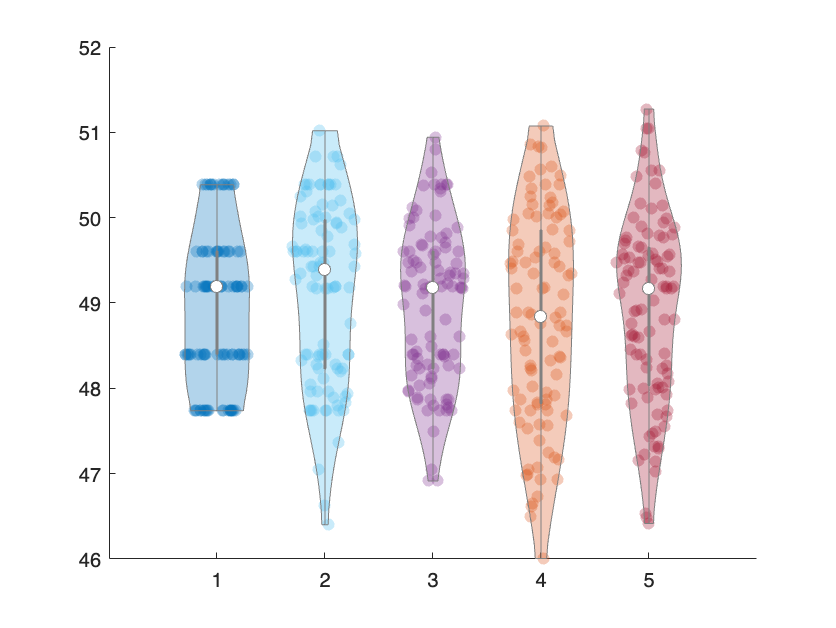

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean



%Plotting the mean of the 100 iterations of the random CHH over intances_comb from rule 1-5, feature 4 
results_IS_Exp6_randCHH_means=squeeze(mean(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,4,:)));
figure
violinplot(results_IS_Exp6_randCHH_means)

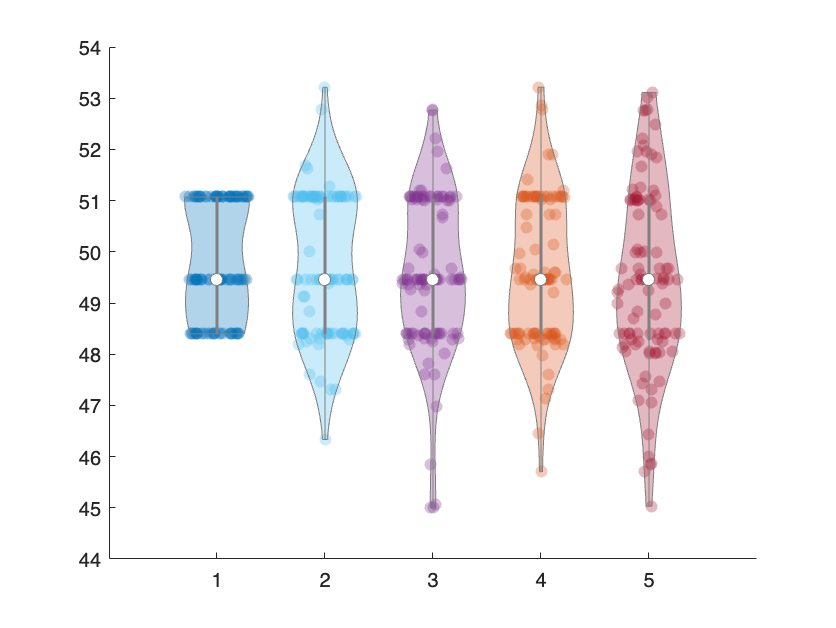

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean



%Plotting the mean of the 100 iterations of the random SHH over intances_comb from rule 1-5, feature 5 
results_IS_Exp6_randSHH_means=squeeze(mean(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,5,:)));
figure
violinplot(results_IS_Exp6_randSHH_means)

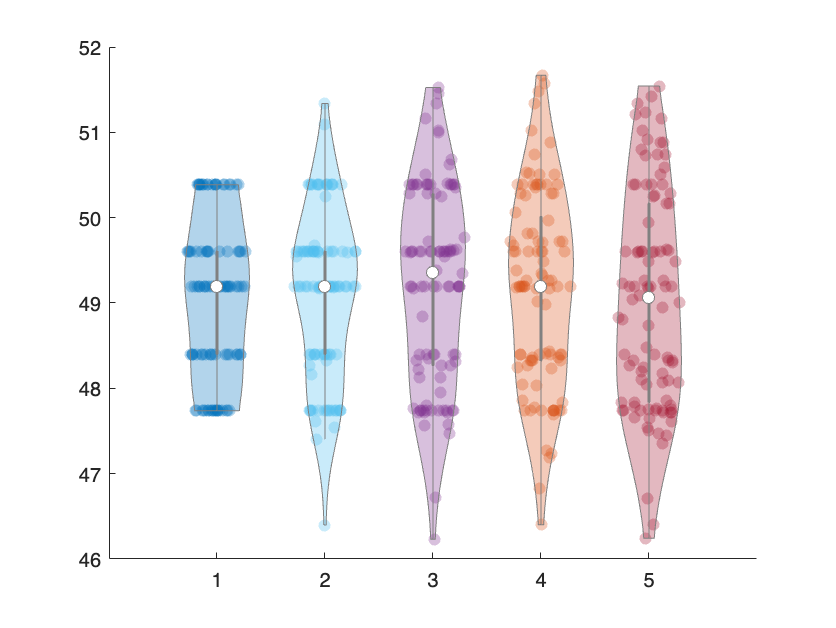

ans =   1×5 Violin array with properties:

    ScatterPlot
    ViolinPlot
    BoxPlot
    WhiskerPlot
    MedianPlot
    NotchPlots
    MeanPlot
    ViolinColor
    ViolinAlpha
    EdgeColor
    BoxColor
    BoxWidth
    MedianColor
    ShowData
    ShowNotches
    ShowMean



%Plotting the mean of the 100 iterations of the random CHH over intances_comb from rule 1-5, feature 5 
results_IS_Exp6_randCHH_means=squeeze(mean(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,5,:)));
figure
violinplot(results_IS_Exp6_randCHH_means)